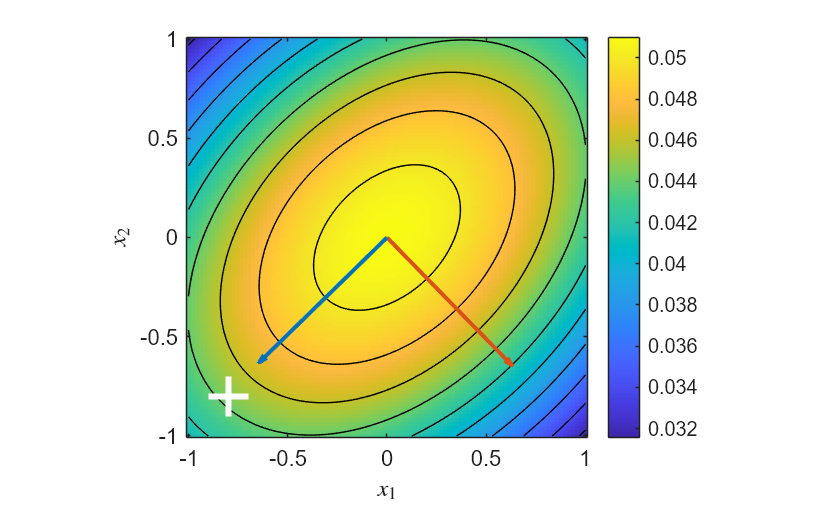


tic
%% types of bivariate gaussian

bi_norm = @(x, mu, S) (2*pi)^(-1)/sqrt(det(S)) * exp(-1/2 * (x - mu)' * inv(S) * (x - mu));

[X, Y] = meshgrid(linspace(-1, 1, 100));
mu = [0; 0];

s11 = 3.41;
s12 = 1.3;
s22 =3.35;

S1 = [s11, s12; s12, s22];

% Vectorize the input for bi_norm
Z = zeros(size(X));
points = [X(:), Y(:)]'; % Create a 2xN matrix of points
for i = 1:size(points, 2)
    Z(i) = bi_norm(points(:, i), mu, S1);
end
Z = reshape(Z, size(X)); % Reshape back to the grid size

figure;
imagesc(linspace(-1, 1, 100), linspace(-1, 1, 100), Z);
hold on;
contour(linspace(-1, 1, 100), linspace(-1, 1, 100), Z, 'color', 'k');
plot(-0.8, -0.8, 'w+', 'markersize', 20, 'linewidth', 3);
set(gca, 'ydir', 'normal');
colorbar;
xlabel('$x_1$', 'interpreter', 'latex');
ylabel('$x_2$', 'interpreter', 'latex');
set(gca, 'fontsize', 11);
axis square;

[V, ~] = eig(S1);
quiver(0, 0, V(1, 1), V(2, 1), 'color', [0.85, 0.325, 0.098], 'linewidth', 2);
quiver(0, 0, V(1, 2), V(2, 2), 'color', [0, 0.4470, 0.7410], 'linewidth', 2);

toc

Elapsed time is 0.223003 seconds.
